## TOPIC 11: Revisiting arrays, pt. 4; function handles

ENGR105, 10/8/20

What makes a good computational solution:

- **Correct**: it works for all (or at least a specific set) of conditions

- **Clear**: it is well-commented, concise, easy to understand, readable

- **Computationally efficient**: it performs a task quickly while minimizing any unnecessary operations

#### Practice Problem: process engineering in a medical environment

As a process engineer in a hospital, your task is to produce a computational framework for assigning doses of drugs to patients based upon their current (relative to prior) blood pressure. As described in the following schematic, your script should extract information from a starting matrix, perform some computations, and produce two output matrices. 

 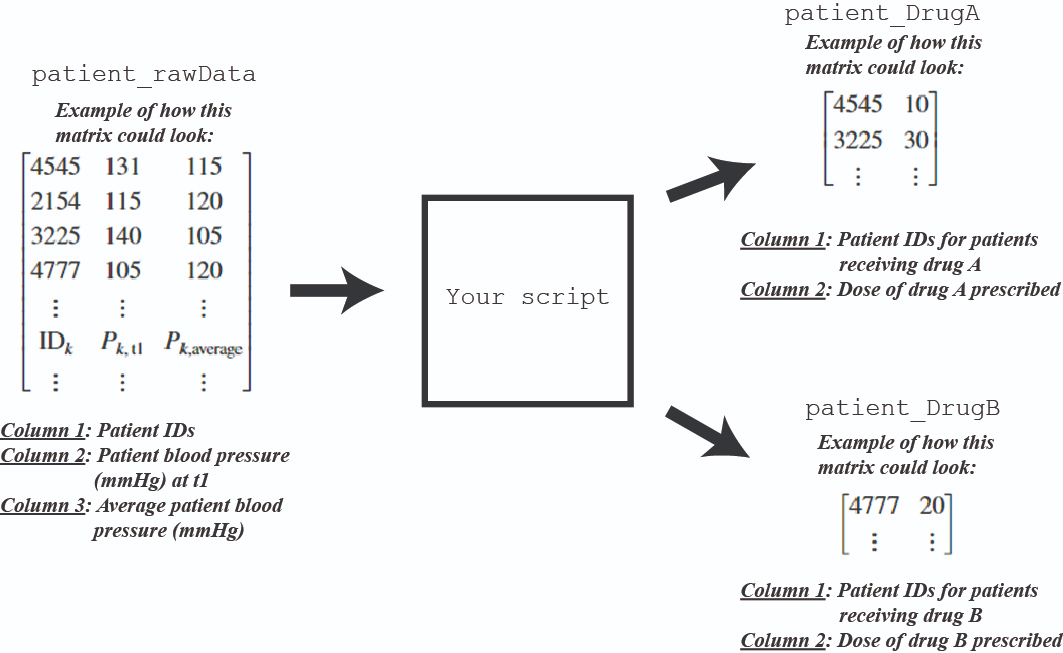

In this problem, the input is an **Nx3 matrix**, where **N is the number of patients with the aforementioned illness** (where N changes daily). Call this matrix: **patient_rawData**

Furthermore, assume each patient in the database has the same medical condition: that patient’s **systolic blood pressure (relative to that patient’s baseline)** determines if that patient should receive **drug A, drug B,** or **no medication**. The decision tree describing how doses are assigned to *each* patient is below:

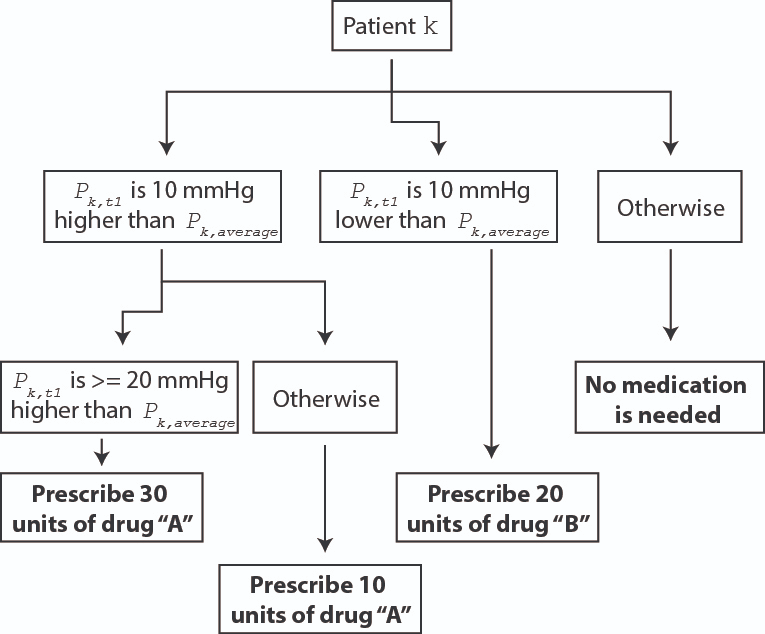

**Goal****: Create a script** to convert **patient_rawData** into two new matrices: one matrix (**patient_DrugA** ) for all patients receiving **drug A**, and another matrix (**patient_DrugB**) for all patients receiving **drug B**.

- Both **patient_DrugA** and **patient_DrugB** should have two columns. As with **patient_rawData**, each row in **patient_DrugA** and **patient_DrugB** should correspond to a unique patient.

- For both **patient_DrugA** and **patient_DrugB**, the first column should contain the patient IDs and the second column should contain the doses of drug to be administered to the corresponding patients.

- **patient_DrugA** should only contain patients who should be assigned Drug A and **patient_DrugB** should only contain patients who should be assigned Drug B.

- If a patient should not be prescribed either drug, then they should **NOT** show up in either **patient_DrugA** or **patient_DrugB.**

Pre-solution code: before solving this problem, let's create a "test" patient_raw Data matrix:

% Create a test matrix of containing simulated patient information
N = 10; % Number of patients

% Input matrix containing patient information
patient_rawData = [(1:N)',randi(50,[N,2])+100];
disp(patient_rawData)

     1   141   108
     2   146   149
     3   107   148
     4   146   125
     5   132   141
     6   105   108
     7   114   122
     8   128   146
     9   148   140
    10   149   148



**Solution 1 **

- **Define output matrices as empty initially**

- **Add the appropriate patient ID and dose (determined from code) to "next row" of output matrices**

% Step 1: Define output arrays - we will populate these as we sequentially
% go through each for loop.

patient_DrugA = [];
patient_DrugB = [];


% Step 2: For each patient, compare their blood pressure at time t1 to
% their average blood pressure to determine if they should receive meds

% Use a FOR loop because we know how many iterations to perform -> one for
% each row of patient_rawData because each row in patient_rawData
% corresponds to one patient
for k = 1:size(patient_rawData, 1)
    
    % NOTE: the columns contain the following information:
    % patient_rawData(k,1): four-digit patient ID
    % patient_rawData(k,2): P_t1: blood pressures of patients at time t1
    % patient_rawData(k,3): P_avg: average recent patient blood pressures
    
    % if P_t1 - P_avg >= 10, determine if a dose of 10 or 30 should be
    % applied
    if patient_rawData(k,2) - patient_rawData(k,3) >= 10
        
    % if P_t1 - P_avg >= 20 -> assign to patient_DrugA and presribe a dose
    % of 30
        if patient_rawData(k,2) - patient_rawData(k,3) >= 10
            
            % Add a row to patient_DrugA, with the first entry being the
            % patient ID and the second being a dose of 30
            patient_DrugA(end+1,1:2) = [patient_rawData(k,1), 30];
        
         
        % if P_t1 - P_avg >= 10 -> assign to patient_DrugA and presribe a dose
        % of 10
        else
            % Add a row to patient_DrugA, with the first entry being the
            % patient ID and the second being a dose of 10
            patient_DrugA(end+1,1:2) = [patient_rawData(k,1), 10];
        end    

        
    % if P_t1 - P_avg < 10 -> assign to patient_DrugB and presribe a dose
    % of 20
    elseif patient_rawData(k,2) - patient_rawData(k,3) <= -10
    
        % Add a row to patient_DrugA, with the first entry being the
        % patient ID and the second being a dose of 10
        patient_DrugB(end+1, 1:2) = [patient_rawData(k,1), 20];

    end
end 
      
disp(patient_DrugA)

     1    30
     4    30



disp(patient_DrugB)

     3    20
     8    20



**Common issues **

- **Array indexing. **Be careful with the indexing inside of the `for` loop. This will define which entries of the output matrices are populated.

- `If-elseif`** statements vs. nested **`if`** statements: **in general, try to avoid nested `if` statements. These are fine if they are clear, but my experience has been that simpler `if-elseif` statements can more concisely convey a piece of code.

- **For loop syntax. **The index of the `for` loop does not need to be defined prior to the for loop. Also, specifying the loop to be performed for the loop index equaling one number is not valuable -- we want to specify a vector over which the index may be repeated.

- **For loops vs. while loops**. When should you use one vs. the other? If you use a while loop when a for loop is more appropriate, it may cause unintended confusion.

- **Built-in array functions**. What are the advantages and disadvantages of different ones? When should you use `length()` vs. `size()`. In general, I am against memorizing functions. However, these two are extremely useful if used correctly.

In other words, just solving a problem is not the only thing that matters. It also matters *how* you solve the problem.

**Solution 2**

- **Preallocate output matrices with the same number of rows as **`patient_rawData`

- **Add the appropriate patient ID and dose (determined from code) to the next row using a counter**

- **Delete all empty (ununsed) rows**


% Step 1: Define output arrays - we will populate these as we sequentially
% go through each for loop.

patient_DrugA = zeros(size(patient_rawData,1),2);
patient_DrugB = zeros(size(patient_rawData,1),2);;


%create counters to keep track or rows for the patients 
rowA = 1;
rowB = 1; 

% Step 2: For each patient, compare their blood pressure at time t1 to
% their average blood pressure to determine if they should receive meds

% Use a FOR loop because we know how many iterations to perform -> one for
% each row of patient_rawData because each row in patient_rawData
% corresponds to one patient
for k = 1:size(patient_rawData, 1)
    
    % NOTE: the columns contain the following information:
    % patient_rawData(k,1): four-digit patient ID
    % patient_rawData(k,2): P_t1: blood pressures of patients at time t1
    % patient_rawData(k,3): P_avg: average recent patient blood pressures
    
    % if P_t1 - P_avg >= 10, determine if a dose of 10 or 30 should be
    % applied
    if patient_rawData(k,2) - patient_rawData(k,3) >= 10
        
    % if P_t1 - P_avg >= 20 -> assign to patient_DrugA and presribe a dose
    % of 30
        if patient_rawData(k,2) - patient_rawData(k,3) >= 10
            
            % Add a row to patient_DrugA, with the first entry being the
            % patient ID and the second being a dose of 30
            patient_DrugA(end+1,1:2) = [patient_rawData(k,1), 30];
            
         
        % if P_t1 - P_avg >= 10 -> assign to patient_DrugA and presribe a dose
        % of 10
        else
            % Add a row to patient_DrugA, with the first entry being the
            % patient ID and the second being a dose of 10
            patient_DrugA(end+1,1:2) = [patient_rawData(k,1), 10];
        end    

        
    % if P_t1 - P_avg < 10 -> assign to patient_DrugB and presribe a dose
    % of 20
    elseif patient_rawData(k,2) - patient_rawData(k,3) <= -10
    
        % Add a row to patient_DrugA, with the first entry being the
        % patient ID and the second being a dose of 10
        patient_DrugB(end+1, 1:2) = [patient_rawData(k,1), 20];

    end
end 
      
disp(patient_DrugA)

     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     1    30
     4    30



disp(patient_DrugB)

     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     3    20
     8    20



**Solution 3**

- **Use logical indexing to directly create the output matrices**

- **This is the "vectorization" equivalent**

% Create matrix for patients recieiveing drug A

%create submatrix consisting only of patients that need Drug A
patient_DrugA = patient_rawData(patient_rawData(:,2) - patient_rawData(:,3) >= 10,:);

%Use logival array indexing to determine the dose of drugs each patient
%should recive. Create a new column to clculate doses based on the
%patient's blood pressure and avg blood pressure 

patient_DrugA(:,4) = 10 + 20*(patient_DrugA(:,2) - patient_DrugA(:,3) >= 20); 
        
%Delete the unnecessary columns -> we do not want columns corresponding to patient blood pressure or the avg blood pressure.         
patient_DrugA(:,2:3) = [];        
        

%Step 2: Create matrix for patients recieving drub B

%Create a column vector consisting of only patients that will need drub B
patient_DrugB = patient_rawData(patient_rawData(:,2) - patient_rawData(:,3) <= 10,1);

%use logival array indexing to deremine the dose of drugs each person
%should receive. Create a new column containing the dose 20 -- all
patient_DrubB(:,2) = 20; 

disp(patient_DrugA)

     1    30
     4    30



disp(patient_DrugB)      

     2
     3
     5
     6
     7
     8
     9
    10



For fun, we can** compare the computational time for each of these solutions** using the approach we have discussed previous. To conserve space, only the output is shown here.

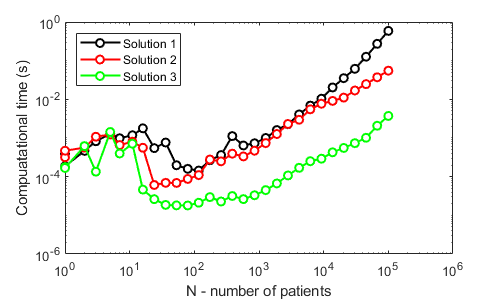

**Takeaways**

- **Clear comments and pseudocode** go a long way towards helping you understand a problem and develop a clear, robust solution.

- Avoid nested if statements, if possible.

- Understanding a decision tree is critical for developing an if statement, but also for producing a solution using logical arrays.

- **Pay particular attention to the***** form*** of the output.

- **Vectorized solutions (e.g. using logical arrays) are simpler, faster, and easier to read.**

### Increasing computation efficiency with arrays (continued from last time):

#### Always preallocate arrays

As we saw with vectors, preallocation is the process of creating an array of the final size (usually padded with zeros) before modifying each element of the array.** Consider the computational time associated with creating an NxN multiplication table** using `for` loops for different numbers of N.

That is, what we want to create:

            
$$\left\lbrack \begin{array}{cccccc}
1 & 2 & 3 & 4 & 5 & \cdots \\
2 & 4 & 6 & 8 & 10 & \cdots \\
3 & 6 & 9 & 12 & 15 & \cdots \\
4 & 8 & 12 & 16 & 20 & \cdots \\
5 & 10 & 15 & 20 & 25 & \cdots \\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \ddots 
\end{array}\right\rbrack$$


% Determine range of N
N = logspace(0,3,4);

% Preallocate vectors to store computational time
t_no = zeros(length(N),1);
t_yes = zeros(length(N),1);

% For each number of elements considered
for k = 1:length(N)
    
    % Calculate time without preallocation
    tic;
    % For each row
    for jj = 1:N(k)
        % For each column
        for mm = 1:N(k)
            % Each entry is the produce of the rows and columns of the
            % multiplication table
            multTable(jj,mm) = jj*mm;
        end
    end
    t_no(k) = toc;
    
    % Calculate time without preallocation
    tic;
    % Preallocate array
    multTable = zeros(N(k),N(k));
    
    % For each row
    for jj = 1:N(k)
        % For each column
        for mm = 1:N(k)
            % Each entry is the produce of the rows and columns of the
            % multiplication table
            multTable(jj,mm) = jj*mm;
        end
    end
    t_yes(k) = toc;
    
    % Delete multiplication table so that it can be created from scratch on
    % the next loop
    clear multTable 
end

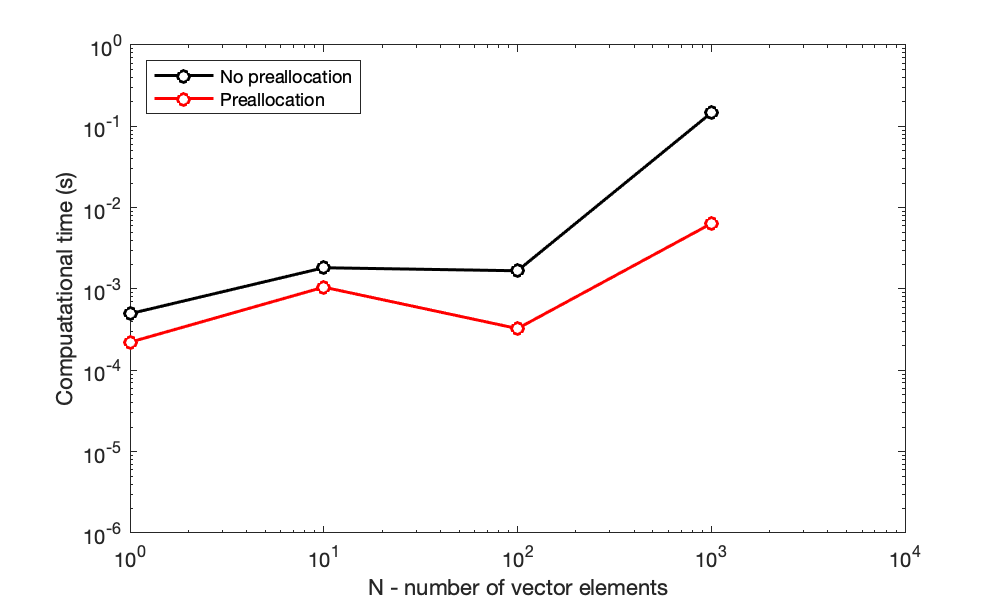

% Define dimensions of plot
figure('Position',[0,0,500,300]);
% Plot the functions
plot(N,t_no,'ko-',N,t_yes,'ro-','LineWidth',1.5,'MarkerFaceColor','auto')
% Graphical parameters
set(gca, 'XScale', 'log')   % "log" axes - x
set(gca, 'YScale', 'log')   % "log" axes - y
set(gca,'XMinorTick','on')
xlim([10^0,10^4]);  % range of x values on plot
ylim([10^-6,10^0]); % range of y values on plot
xlabel('N - number of vector elements');
ylabel('Compuatational time (s)');
legend('No preallocation','Preallocation','Location','northwest')

**Side note**: the above multiplication table can be created **much more efficiently** using **matrix multiplication **instead of nested for loops.

multTable = (1:10)'*(1:10)

multTable =      1     2     3     4     5     6     7     8     9    10
     2     4     6     8    10    12    14    16    18    20
     3     6     9    12    15    18    21    24    27    30
     4     8    12    16    20    24    28    32    36    40
     5    10    15    20    25    30    35    40    45    50
     6    12    18    24    30    36    42    48    54    60
     7    14    21    28    35    42    49    56    63    70
     8    16    24    32    40    48    56    64    72    80
     9    18    27    36    45    54    63    72    81    90
    10    20    30    40    50    60    70    80    90   100


#### Sparse arrays

Sparse matrices -- large arrays with few nonzero entries -- are encountered in a broad set of engineering disciplines, with applications including solving PDEs, search algorithms, atomistics, and FEA. 

        
$$\left\lbrack \begin{array}{ccccc}
0 & 0 & 0 & 0 & 0\\
0 & 0\ldotp 5 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 2\ldotp 8 & 0\\
3 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$$


Consider a sparse matrix of dimensions 1000 x 2000 elements - that correlates to 2 million data points. Assume that this matrix contains non-zero values at the following indices:

- (row 3, column 4) = 15

- (row 100, column 1500) = 5

- (row 1000, column 2000) = 9

This matrix may be established using a conventional matrix indexing:

A = zeros(1000,2000);
A(3,4) = 15;
A(100,1500) = 5;
A(1000,2000) = 9;

Sparse matrices can be stored efficiently as a matrix of 0’s with nonzero values stored by their row, column, and value – this can save significant memory space. In the above example, this matrix could also be established using a sparse matrix syntax:

B = sparse([3,100,1000],...
    [4,1500,2000],...
    [15,5,9],1000,2000);

Or, the original non-sparse matrix `A` could also be converted to a sparse matrix:

B = sparse(A);

**The sparse matrix offers considerable savings for memory**. Information about a variable can be depicted using the `whos` command.

whos A B

  Name         Size                 Bytes  Class     Attributes

  A         1000x2000            16000000  double              
  B         1000x2000               16056  double    sparse    



In this case, variable A requires 16 MB of memory to create the **full matrix**, whereas variable B (**the sparse array**) only requires 16 kB! Dramatic savings in memory can be observed when most of the elements are zero.

**At what number of nonzero elements do sparse matrices lose this advantage?** Let's plot the memory associated with a matrix variable for different numbers of nonzero elements in a 100x100 matrix.

% Define a matrix intially with all zeros
A = zeros(100,100);

% Preallocate vector to store memory
mem_Full = zeros(1,numel(A));
mem_Sparse = zeros(1,numel(A));

% Repeat for all elements
for k = 1:numel(A)
    A(k) = randi(5);
    
    A_sparse = sparse(A);
    
    matrixInfo = whos('A','A_sparse');
    mem_Full(k) = matrixInfo(1).bytes;
    mem_Sparse(k) = matrixInfo(2).bytes;
end

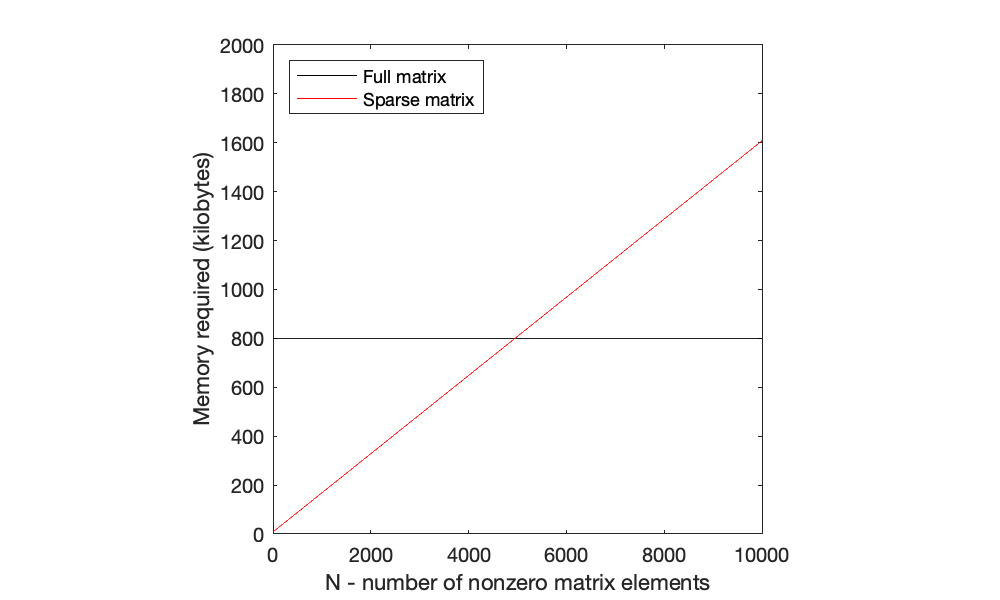

% Plot the functions
plot(1:numel(A),mem_Full/100,'k-',1:numel(A),mem_Sparse/100,'r-')

% Graphical parameters
axis square
xlim([0,10^4]);  % range of x values on plot
ylim([0,2*10^3]); % range of y values on plot
xlabel('N - number of nonzero matrix elements');
ylabel('Memory required (kilobytes)');
legend('Full matrix','Sparse matrix','Location','northwest')

Since sparse variables need to also store information about the nonzero indices, these variables will require more space when more entries are full. In addtion to memory, a similar dramatic savings in computational time when working with sparse arrays can be observed by using `tic` and `toc`, as we have done previously. 

**Note**: if you need to convert a sparse matrix to a full matrix, this can be accomplished using `full()`.

### Revisiting functions

As we have seen so far in this class, functions are** named assemblages of code** that perform specific tasks. By encapsulating sections of code in functions, we can call the function to efficiently repeat the enclosed tasks, while potentially changing any number of inputs.

Functions:

- Take in inputs (from none to many)

- Return outputs (from none to many)

- Are created with a function declaration (at the end of the LiveScript document or in a separate .m file)

In terms of precedence, commas in a function declaration can be thought of as having the lowest precedence. That is, commas separate inputs, even if the inputs themselves are complicated expressions.

A = 1:4

A =      1     2     3     4


B = A > 2

B = 1×4 logical array
   0   0   1   1


% Sum over all rows
sum(((A>2) | A == 1),1)

ans =      1     0     1     1


Consider the function `square_add1`, below, which has 2 inputs and 1 output. This function is stored at the end of this LiveScript document.

Functions are properly called by matching the form of the function declaration in your script.

val1 = 1; 
val2 = 2;

% Call function
x = square_add1(val1,val2)

x = 6

**Note**: the definition of inputs `a`, `b`, and `c` are unique to the function itself and** can't be seen by the memory workspace** from which the function was invoked.

A common struggle when learning about functions is (unintentionally) **not capturing all of the outputs when invoking the functions**. Consider the function `addMultiply`.

The following would **only capture the first output** of `addMultiply` (`res1` in the function declaration) and store it in `ans` (the default variable when no assignment is described) as no output assignment is declared. 

If only one output is desired, use a **tilde **to** suppress the undesirable output. **The tilde in this case says "this first output is defined/required by the function, but I don't want it…I just want the second output"

#### Function handles

Functions can be passed as variables and referenced/invoked by using this new variable. A variable that has been assigned to a function is referred to as a function handle. Consider our previous function.

To create a function handle, use the `@` symbol. This indicates that the variable is a function handle and not a data type. The following is an example of assigning the function `square_add1` to the function handle a

% Create a function handle
f1 = @square_add1;
% Use the function handle. Note the scalar inputs are passed to the
% function in the same way as before.
y = f1(1,2)

y = 6

**Important feature****: function handles enable us to pass a function as an input** into another function.

% Create function handle for new function
f2 = @operateOnKnownValues

f2 = function_handle with value:
    @operateOnKnownValues


% Input square_add1 into new function
z = f2(@sum)

z = 1

You can create function handles for **built-in functions** in addition to custom functions.

% Create a vecotr
A = 1:4

A =      1     2     3     4


% Create function handle for sum() function
f1 = @sum;
f1(A)

ans = 10

**Example**. Create function handles for the following two functions that are created at the end of this document.

% Function handle for example A
f2 = @exampleA

f2 = function_handle with value:
    @exampleA


% Function handle for example B
f3 = @exampleB

f3 = function_handle with value:
    @exampleB


% Call example function, input sum and A. The following two are equivalent
out1 = f3(@sum,A)

out1 = 9

out2 = f2(f1,A)

out2 = 11

% NOTE: an error will occur if you input a function and not a function
% handle
% out3 = f2(sum,A)

#### Example: force on a spring

In your physics, chemistry, and engineering courses, you will likely encounter Hooke's law, which relates the displacement of the end of a spring (i.e. the stretching or compression of the spring) to the force required to cause that deformation:

            
$$F=k\;x$$


This equation describes a linear dependence of the force on the material deformation. An elastic body or material for which this equation can be assumed is said to be linear-elastic or **Hookean**.

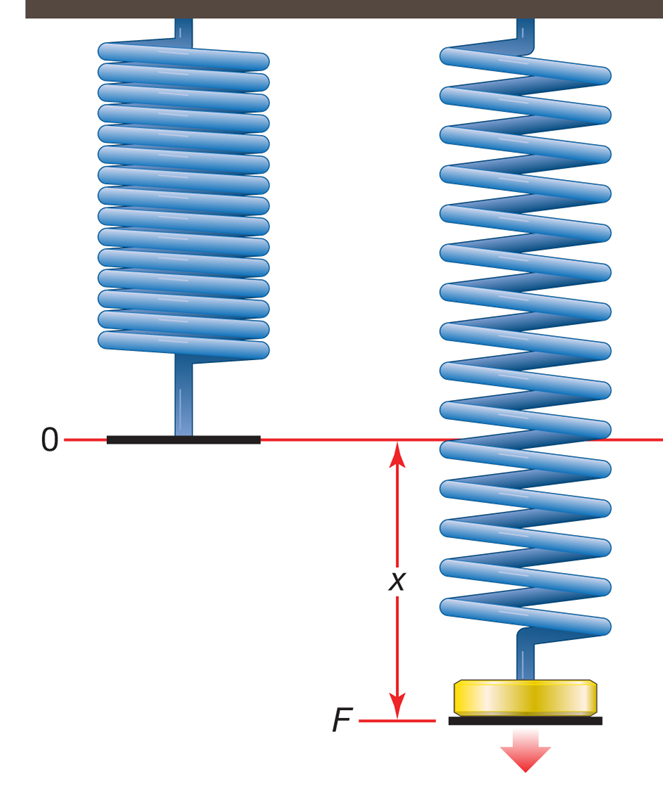

Consider the function `springForce1`, which computes the force on a Hookean spring based on its displacement

The function can be assigned to a function handle and invoked with an input for `delta` from the command line, a script, or another function

% Create function handle
a = @springForce1;
% Call function
myForce = a(4)

myForce = 2

However, **nonlinear springs are also common**, as even the most linear spring can be deformed enough such that a nonlinear relationship between force and deformation becomes apparent. Consider force-displacement relationship for another spring.

Using function handles, we could easily create a modular representation of two springs in parallel.

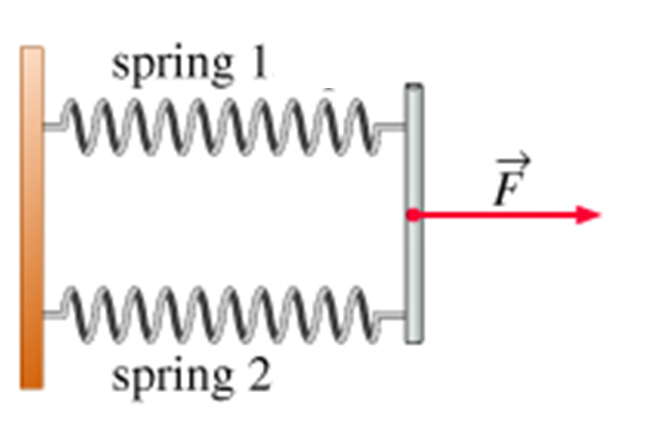

In this case, the net force is determined as the sum of the contributions from each spring, which could be encoded into a separate function.

% Evaluate the total force when spring 1 and 2 are arranged in parallel
force = parallelSprings(@springForce1,@springForce1,5)

force = 5

**Note**: in this way, we use functions to create a framework in which we can easily change different components.

**The following functions are used to introduce function handles.**

function res1 = square_add1(a,b)
    % Example function. In this case there are two inputs and one
    % output. 
    res1 = a^2 + b^2 + 1;
end

function res2 = operateOnKnownValues(fxn)
    % Example function: input 1 is another function
    res2 = fxn(1,2);

end

function res3 = exampleA(fxn,A)
    % Example function: input 1 is a function, input 2 is an array
    res3 = fxn(A) + 1;

end

function res4 = exampleB(fxn,A)
    % Example function: input 1 is a function, input 2 is an array
    res4 = fxn(A) - 1;

end

Functions for Spring example

function force = springForce1(delta)
    % Calculate the force required to cause a deformation of delta
    % Spring constant = 0.5
    force = 0.5*delta;
end

function force = springForce2(delta)
    % Calculate the force required to cause a deformation of delta
    % in a nonlinear spring
    force = .2*delta^2 + .5*delta;
end

function force = parallelSprings(spring1,spring2,delta)
    % Force for two springs loaded in parallel config.
    % spring1 = handle to force/deflection eqn for spring 1
    % spring2 = handle to force/deflection eqn for spring 2
    % delta = displacement of springs
     
    force = spring1(delta) + spring2(delta);
end